# **Digital Communication Systems CA3**

## Golmehr Khosrokhavar - Stident ID : 810198507

## PART 1 : 

### Generting Raised Cosine PULSE : 

- Here we define given parameters in the assignment. Then we are going to generate Raised Cosine in 3 scenarios. The purpose of this action is to see and consider the effect of sampling time error in the final result and final Bit Error Probability.

Beta = 0.5 ;
Beta_0 = 0; 
Beta_1 = 1; 
T = 1; 
Fs = 10 ; 
L = T*Fs; 
delta_t = T/Fs;

#### **first scenario - Ideal Sampling**

sampling_error1 = 0 ; 
t1 = (-6*L : 6*L)/Fs - sampling_error1;
P_r_zeros = zeros (1, length(t1));
P_r = pulse_generator(t1,Beta,T);
P_r_Beta_0 = pulse_generator(t1,Beta_0,T);
P_r_Beta_1 = pulse_generator(t1,Beta_1,T);

plot (t1,P_r)
hold on 

#### Second Scenario - Samling Error = 0.1T

sampling_error2 = 0.1 ; 
t2 = (-6*L : 6*L)/Fs - sampling_error2;
P_r2_zeros = zeros (1, length(t2));
P_r2 = pulse_generator(t2,Beta,T);
P_r2_Beta_0 = pulse_generator(t2,Beta_0,T);
P_r2_Beta_1 = pulse_generator(t2,Beta_1,T);

plot (t2,P_r2)


#### Third Scenario - Sampling Error = 0.2T 

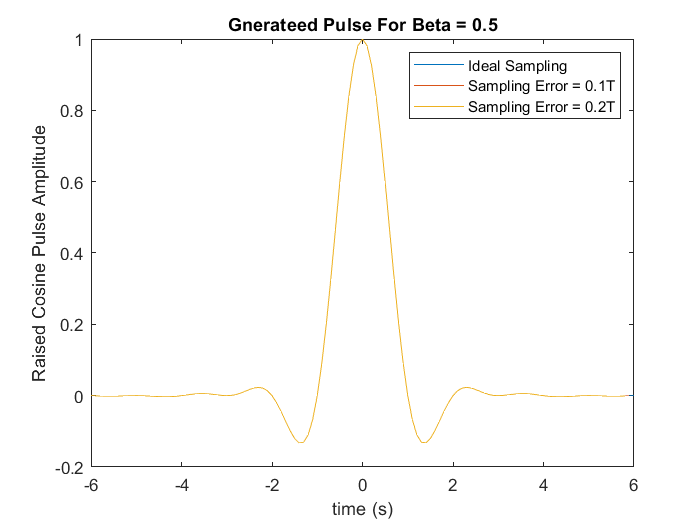

sampling_error3 = 0.2 ; 
t3 = (-6*L : 6*L)./Fs - sampling_error3;
P_r3_zeros = zeros (1, length(t3));
P_r3 = pulse_generator(t3,Beta,T);
P_r3_Beta_0 = pulse_generator(t3,Beta_0,T);
P_r3_Beta_1 = pulse_generator(t3,Beta_1,T);

plot (t3,P_r3)
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
xlabel('time (s)'); ylabel('Raised Cosine Pulse Amplitude');
title ('Gnerateed Pulse For Beta = 0.5');
xlim([-6 6]);
hold off

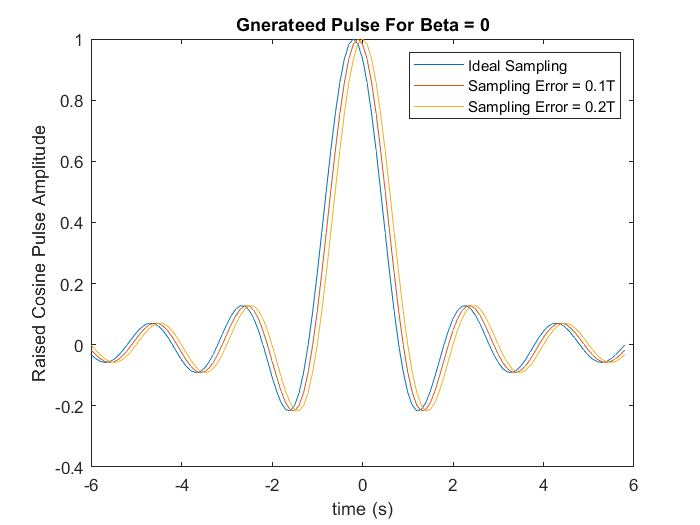

plot (t3,P_r_Beta_0)
hold on 
plot (t3,P_r2_Beta_0)
plot (t3,P_r3_Beta_0)
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
xlabel('time (s)'); ylabel('Raised Cosine Pulse Amplitude');
title ('Gnerateed Pulse For Beta = 0');
xlim([-6 6]);
hold off

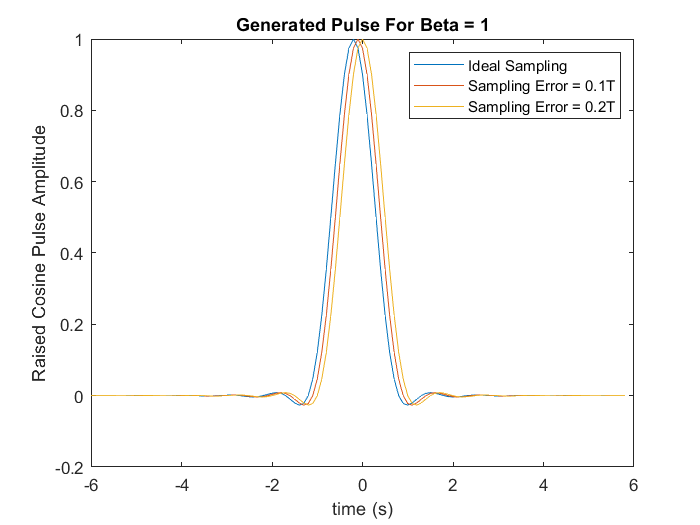


plot (t3,P_r_Beta_1)
hold on 
plot (t3,P_r2_Beta_1)
plot (t3,P_r3_Beta_1)
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
xlabel('time (s)'); ylabel('Raised Cosine Pulse Amplitude');
title ('Generated Pulse For Beta = 1');
xlim([-6 6]);
hold off

## PART 2 : 

### Generating Modulated Symbols : 

as discussed in the assignment, first we make a vector of ${10}^5$ indexes. which is called "bits" and contains random values between 0 and 1 (uniformly distributed) .

"modulated_symbols" is a vector with same size of bits and contains the coded value of "1" as a representation of bits with 1 value and  the coded value of "-1" as a representation of bits with 0 value.

bits =  randi(2,1,100000);
bits = bits -1;
modulated_symbols = zeros(1, length(bits));

for i = 1 : length(bits)
    if (bits(i) == 0 )
        modulated_symbols(i) = -1; 
    else
        modulated_symbols(i) = 1;       
    end
end

#### Upsampling : adding L-1 zeros between each two elements. 

we suppose if each analog span has a length of T and we want to replace it with L samples. Hence we have to add L -1 zeros between each two samples. 

temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));

#### Convolving Upsampled vector of symbols with the raised cosine puse, generate in first part. 

transmitted_signal1 = conv(P_r,temp0);
transmitted_signal2 = conv(P_r2,temp0);
transmitted_signal3 = conv(P_r3,temp0);

transmitted_signal1_Beta_0 = conv(P_r,temp0);
transmitted_signal2_Beta_0 = conv(P_r2_Beta_0,temp0);
transmitted_signal3_Beta_0 = conv(P_r3_Beta_0,temp0);

transmitted_signal1_Beta_1 = conv(P_r,temp0);
transmitted_signal2_Beta_1 = conv(P_r2_Beta_1,temp0);
transmitted_signal3_Beta_1 = conv(P_r3_Beta_1,temp0);


## PART 3 : 

### Simmulating AWGN channel : 

SNR_dB = 0:10;
etta = zeros(1,length(SNR_dB));
 for i = 1:length(etta)
     etta(i) = find_etta(SNR_dB(i));
 end
 Zarib = zeros(1,length(etta));
 Noise = randn(11,length(transmitted_signal1));
  for i = 1:length(etta)
      Zarib(i) = sqrt(etta(i)/2);
      Noise(i,:) = Zarib(i).*Noise(i,:);
 end
 

#### Generating received signals

 [received_signal1, received_signal2, received_signal3] = create_recieved_signal(etta,Noise,transmitted_signal1,transmitted_signal2,transmitted_signal3);
 [received_signal1_Beta_0, received_signal2_Beta_0, received_signal3_Beta_0] = create_recieved_signal(etta,Noise,transmitted_signal1_Beta_0,transmitted_signal2_Beta_0,transmitted_signal3_Beta_0);
 [received_signal1_Beta_1, received_signal2_Beta_1, received_signal3_Beta_1] = create_recieved_signal(etta,Noise,transmitted_signal1_Beta_1,transmitted_signal2_Beta_1,transmitted_signal3_Beta_1);
   

## PART 4 : 

### Detecting Symbols : 

In this part we calculate "received-signal"in sampling times and generate a new vector, named "samples".

Then we compare "samples"with the threshold, which is zero,then  we could decide that the transmitted signal was either -1 or 1. 

#### Generating Samples

 N = 10.^5;
T_sampling = 6*L+1:L:(N+6-1)*L+1;
[samples1,samples2,samples3] = create_samples(T_sampling,received_signal1,received_signal2,received_signal3);
[samples1_Beta_0,samples2_Beta_0,samples3_Beta_0] = create_samples(T_sampling,received_signal1_Beta_0,received_signal2_Beta_0,received_signal3_Beta_0);
[samples1_Beta_1,samples2_Beta_1,samples3_Beta_1] = create_samples(T_sampling,received_signal1_Beta_1,received_signal2_Beta_1,received_signal3_Beta_1);


- Note that "detected_symbols1" is dedicated to  symbols with Ideal Sampling Time,  "detected_symbols2" is dedicated to  symbols with Sampling Error Time = 0.1T, and "detected_symbols3" is dedicated to  symbols with Sampling Error Time = 0.2T.

[detected_symbols1,detected_symbols2,detected_symbols3] = find_detected_symbols(T_sampling,samples1,samples2,samples3);
[detected_symbols1_Beta_0,detected_symbols2_Beta_0,detected_symbols3_Beta_0] = find_detected_symbols(T_sampling,samples1_Beta_0,samples2_Beta_0,samples3_Beta_0);
[detected_symbols1_Beta_1,detected_symbols2_Beta_1,detected_symbols3_Beta_1] = find_detected_symbols(T_sampling,samples1_Beta_1,samples2_Beta_1,samples3_Beta_1);


## PART 5 : 

### Calculating Error Probability : 

#### calculating number of errors:


[num_of_errors1,num_of_errors2,num_of_errors3] = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols1,detected_symbols2,detected_symbols3);
[num_of_errors1_Beta_0,num_of_errors2_Beta_0,num_of_errors3_Beta_0] = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols1_Beta_0,detected_symbols2_Beta_0,detected_symbols3_Beta_0);
[num_of_errors1_Beta_1,num_of_errors2_Beta_1,num_of_errors3_Beta_1] = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols1_Beta_1,detected_symbols2_Beta_1,detected_symbols3_Beta_1);


#### Calculating Error Probability

we consider error probability be : 

- Note that "P_e1" is probability dedicated to symbols with Ideal Sampling Time,  "P_e2" is  probability dedicated to  symbols with Sampling Error Time = 0.1T, and  "P_e3" is  probability dedicated to  symbols with Sampling Error Time = 0.2T.

P_e1 = zeros(11,1);P_e2 = zeros(11,1);P_e3 = zeros(11,1);
P_e1_Beta_0 = zeros(11,1);P_e2_Beta_0 = zeros(11,1);P_e3_Beta_0 = zeros(11,1);
P_e1_Beta_1 = zeros(11,1);P_e2_Beta_1 = zeros(11,1);P_e3_Beta_1 = zeros(11,1);

#### Calculating Error Probability:

P_e1 = num_of_errors1/N;
P_e2 = num_of_errors2/N;
P_e3 = num_of_errors3/N;

P_e1_Beta_0 = num_of_errors1_Beta_0/N;
P_e2_Beta_0 = num_of_errors2_Beta_0/N;
P_e3_Beta_0 = num_of_errors3_Beta_0/N;
 
P_e1_Beta_1 = num_of_errors1_Beta_1/N;
P_e2_Beta_1 = num_of_errors2_Beta_1/N;
P_e3_Beta_1 = num_of_errors3_Beta_1/N;

#### Plotting the results:

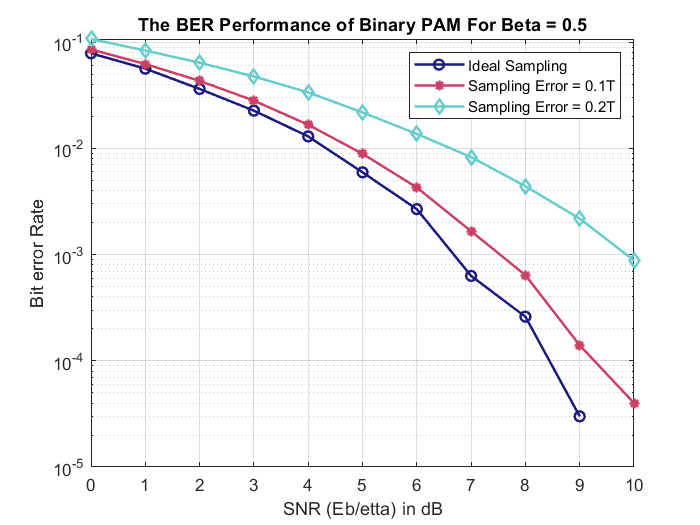


p1 =semilogy (SNR_dB , P_e1,'LineWidth',1.5);

p1.Color = [0.1,0.1,0.5];
p1.Marker = "o";
hold on 
p2 = semilogy (SNR_dB , P_e2,'LineWidth',1.5);
p2.Color = [0.8, 0.25, 0.4];
p2.Marker = "*";
p3 = semilogy (SNR_dB , P_e3,'LineWidth',1.5);
p3.Color = [0.4, 0.8, 0.8];
p3.Marker = "d";
grid on
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
title ('The BER Performance of Binary PAM For Beta = 0.5');
xlabel('SNR (Eb/etta) in dB'); ylabel ('Bit error Rate');
 hold off

Above we can see the Intersymbol Interference caused by the sampling error with Beta = 0.5

Note that the final probability value of Ideal sampling is aound ${10}^{-3}$. 

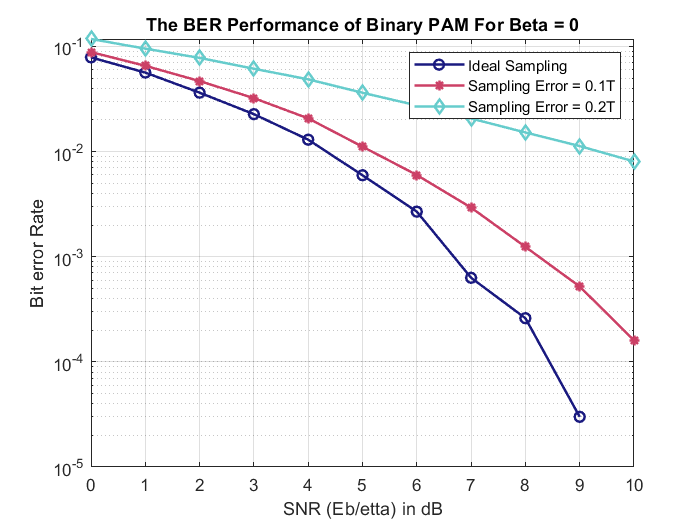

 p1 =semilogy (SNR_dB , P_e1_Beta_0,'LineWidth',1.5);
p1.Color = [0.1,0.1,0.5];
p1.Marker = "o";
hold on 
p2 = semilogy (SNR_dB , P_e2_Beta_0,'LineWidth',1.5);
p2.Color = [0.8, 0.25, 0.4];
p2.Marker = "*";
p3 = semilogy (SNR_dB , P_e3_Beta_0,'LineWidth',1.5);
p3.Color = [0.4, 0.8, 0.8];
p3.Marker = "d";
grid on
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
title ('The BER Performance of Binary PAM For Beta = 0');
xlabel('SNR (Eb/etta) in dB'); ylabel ('Bit error Rate');
 hold off

Above we can see the Intersymbol Interference caused by the sampling error with Beta = 0

Note that the final probability value of Ideal sampling is aound ${10}^{-2}$. 

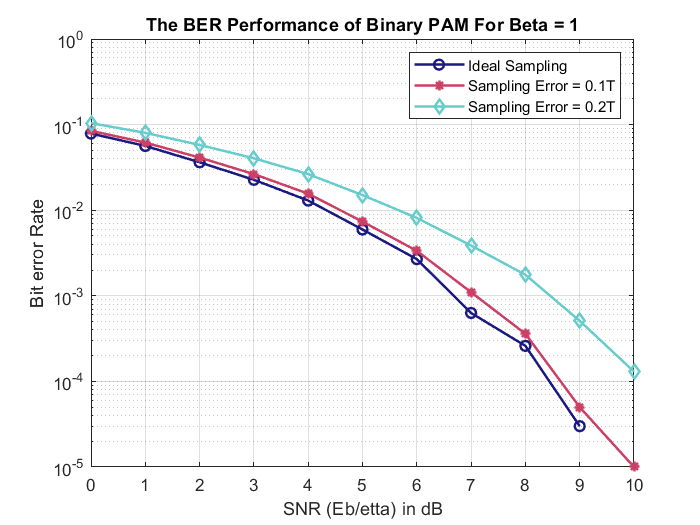

 
  p1 =semilogy (SNR_dB , P_e1_Beta_1,'LineWidth',1.5);

p1.Color = [0.1,0.1,0.5];
p1.Marker = "o";
hold on 
p2 = semilogy (SNR_dB , P_e2_Beta_1,'LineWidth',1.5);
p2.Color = [0.8, 0.25, 0.4];
p2.Marker = "*";
p3 = semilogy (SNR_dB , P_e3_Beta_1,'LineWidth',1.5);
p3.Color = [0.4, 0.8, 0.8];
p3.Marker = "d";
grid on
legend('Ideal Sampling ','Sampling Error = 0.1T', 'Sampling Error = 0.2T');
title ('The BER Performance of Binary PAM For Beta = 1');
xlabel('SNR (Eb/etta) in dB'); ylabel ('Bit error Rate');
 hold off

Above we can see the Intersymbol Interference caused by the sampling error with Beta = 1

Note that the final probability value of Ideal sampling is aound ${10}^{-4}$. 

### **Conclusion**

#### The effect of changing Beta on ISI 

For Beta = 1, we have the least Bit error Probability of all three scenarios, which means we have the least InterSymbol Interference effect.

For Beta = 0, we have the most Bit error Probability of all three scenarios, which means we have the most InterSymbol Interference effect.

As Beta increses to 1 , we wil have a  more narrow raised cosine pulse at the first place and the pulse is damped faster. 

As the damping procces gets faster, the ISI error caused by sampling error will decrease which could be perfectly demonstrated on the graphs above. 

#### The effect of Sampling Error on ISI 

It can be observed from the three graghs that as we increase the sampling error from 0.1T to 0.2 T , the Bit Error Probability will increase either. 

## Functions

function etta = find_etta(SNR_dB)
   temp = 0.1.*SNR_dB;
   etta = 1/(10.^(temp));
end

function P_r = pulse_generator(t1,Beta,T)
    p_1 = zeros (1, length(t1));
    m1 = find(abs(t1-(T/(2*Beta)))<0.0000000000000001);
    m2 = find(abs(t1+(T/(2*Beta)))<0.0000000000000001);
    for i1 = 1: length(t1)
        i = t1(i1);
        if i1==m1
            P_r(i1) = (pi/4).*sinc(1./(2.*Beta));
        elseif i1==m2
            P_r(i1) = (pi/4).*sinc(1./(2.*Beta));
        else 
            P_r(i1) = sinc(i./T).*cos(pi.*Beta.*i/T)/(1-(2.*Beta.*i/T).^2);
        end
       
    end
end

function [detected_symbols1,detected_symbols2,detected_symbols3] = find_detected_symbols(T_sampling,samples1,samples2,samples3)

    detected_symbols1 = zeros(11,length(T_sampling));
    detected_symbols2 = zeros(11,length(T_sampling));
    detected_symbols3 = zeros(11,length(T_sampling));

for j = 1:11
    for i = 1: length(T_sampling)
        
        if ( samples1(j,i) >= 0 )
            detected_symbols1(j,i) = 1;
        else 
            detected_symbols1(j,i) = -1;
        end
        
        if ( samples2(j,i) >= 0 )
            detected_symbols2(j,i) = 1;
        else 
            detected_symbols2(j,i) = -1;
        end
        
        if ( samples3(j,i) >= 0 )
            detected_symbols3(j,i) = 1;
        else 
            detected_symbols3(j,i) = -1;
        end        
        
    end
end 
end

function  [num_of_errors1,num_of_errors2,num_of_errors3] = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols1,detected_symbols2,detected_symbols3)
num_of_errors1 = zeros(11,1);
num_of_errors2 = zeros(11,1);
num_of_errors3 = zeros(11,1);
for j = 1:11
    for i = 1: length(T_sampling)
        
       if (modulated_symbols(i) == detected_symbols1(j,i))
           num_of_errors1(j,1)= num_of_errors1(j,1);
       else 
           num_of_errors1(j,1)= num_of_errors1(j,1) +1;
       end
      
       if (modulated_symbols(i) == detected_symbols2(j,i))
           num_of_errors2(j,1)= num_of_errors2(j,1);
       else 
           num_of_errors2(j,1)= num_of_errors2(j,1) +1;
       end
       
       if (modulated_symbols(i) == detected_symbols3(j,i))
           num_of_errors3(j,1)= num_of_errors3(j,1);
       else 
           num_of_errors3(j,1)= num_of_errors3(j,1) +1;
       end
    end
end 
end

function [samples1,samples2,samples3] = create_samples(T_sampling,received_signal1,received_signal2,received_signal3)
samples1 = zeros(11, length(T_sampling));
samples2 = zeros(11, length(T_sampling));
samples3 = zeros(11, length(T_sampling));

for j = 1 :11
    for i = 1: length(T_sampling)
        samples1(j,i)=received_signal1(j,T_sampling(i));
        samples2(j,i)=received_signal2(j,T_sampling(i));
        samples3(j,i)=received_signal3(j,T_sampling(i));
               
    end
end 

end

function [ received_signal1, received_signal2, received_signal3] = create_recieved_signal(etta,Noise,transmitted_signal1,transmitted_signal2,transmitted_signal3)

 received_signal1 = zeros(11, length(transmitted_signal1));
 received_signal2 = zeros(11, length(transmitted_signal2));
 received_signal3 = zeros(11, length(transmitted_signal3));
 
 for i = 1:length(etta)
     received_signal1(i,:)= transmitted_signal1 + Noise(i,:);
     received_signal2(i,:)= transmitted_signal2 + Noise(i,:);
     received_signal3(i,:)= transmitted_signal3 + Noise(i,:);
     
 end

end